# Question 2

figure;
hold on;
r = 1;
th = 0:pi/50:2*pi;
xunit = r * cos(th);
yunit = r * sin(th);
h = plot(xunit, yunit);

rectangle('Position',[-1 -1 2 2])

N = 10000

N = 10000

x = rand(1 , N) * 2 - 1

x =     0.3003   -0.3564    0.6138   -0.4622   -0.5553    0.1416    0.6445   -0.9932   -0.6569    0.9705   -0.9575    0.8444    0.0792   -0.1176   -0.3069    0.8288   -0.3199    0.6627   -0.1521   -0.0158    0.2653    0.1584   -0.7312   -0.9627    0.9824    0.3429   -0.0011   -0.5564   -0.4289    0.0961    0.7735    0.1380   -0.8995   -0.9724   -0.3614    0.5026   -0.7861   -0.2071   -0.6282   -0.6587    0.4481   -0.0550   -0.3979   -0.6053    0.2138    0.2225    0.4122   -0.4579   -0.4191   -0.4413


y = rand(1 , N) * 2 - 1

y =     0.5875   -0.2557   -0.5417    0.8438    0.4194    0.2099   -0.8104   -0.3867   -0.1288   -0.3726    0.7654   -0.4377    0.2173    0.1653    0.5809    0.9583   -0.8594   -0.6015    0.3789   -0.6765    0.3781   -0.2709   -0.8863    0.9095    0.0723    0.4258    0.5422   -0.2060   -0.7251   -0.5769   -0.1221   -0.2990    0.7095    0.9954   -0.5173   -0.7282   -0.0052   -0.9226   -0.1689    0.9608    0.5790    0.1914   -0.2821    0.5568   -0.0723    0.3477    0.2793    0.7721    0.8628   -0.6842



sz = 15;

c = zeros(1, length(x));
count = 0;

for i=1:length(x)
    x1 = x(1,i);
    y1 = y(1,i);
    h = sqrt((x1^2) + (y1^2));
    if h <= 1
        count = count + 1;
        c(1, i) = 1;
    else
        c(1, i) = 0;
    end
end

scatter(x,y,sz,c,'filled')

x0=10;
y0=10;
width=550;
height=520;
set(gcf,'position',[x0,y0,width,height])

count

count = 7874


pi_estimation = 4 * (count / N)

pi_estimation = 3.1496

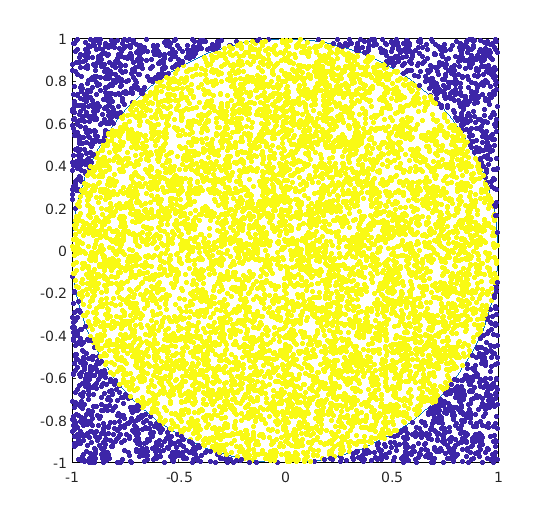

saveas(gcf,'100points.jpg')